# 1. Damping Reduction Factor

## Generate damping reduction factor Bd and Ba of the attached ground motions (40 chi-chi earthquake records) with damping ratios 2%, 5%, 10%, and 20% and with structural periods 0.2 sec, 1 sec, 2 sec, and 4 sec.

## (1) Plot the scatter diagram (Bd or Ba vs. structural periods) with each damping ratio.

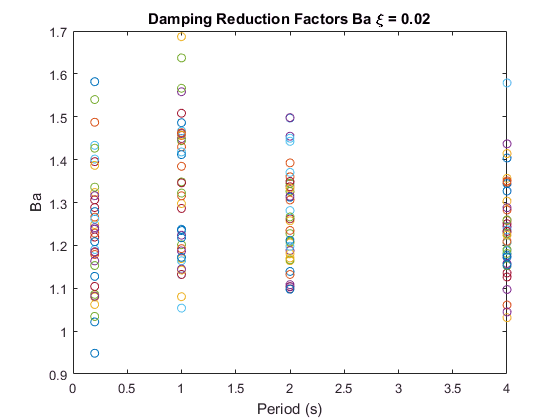

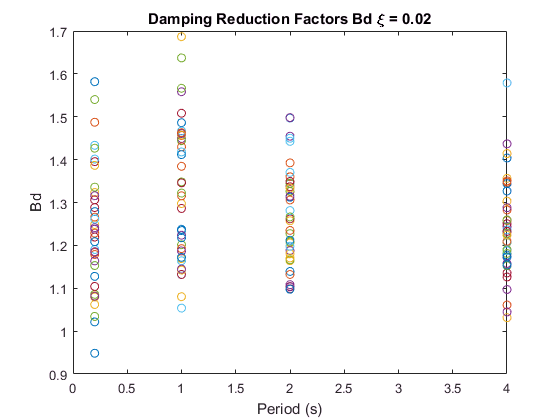

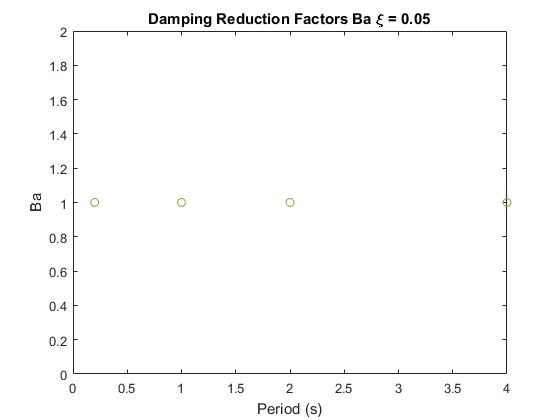

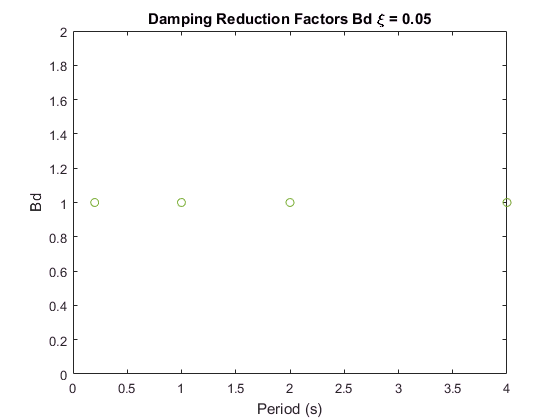

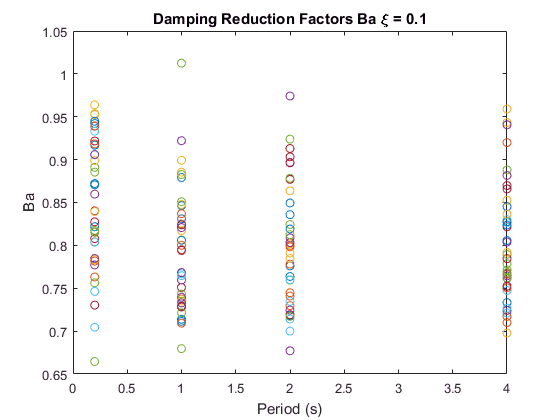

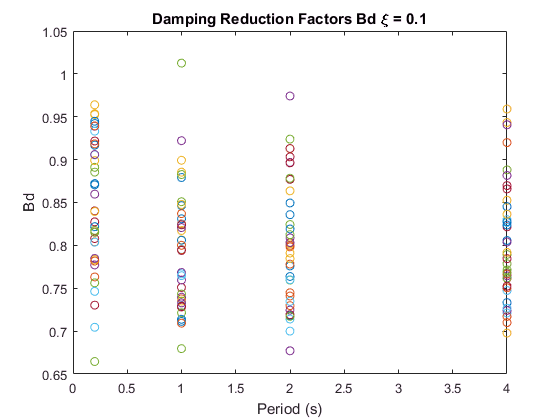

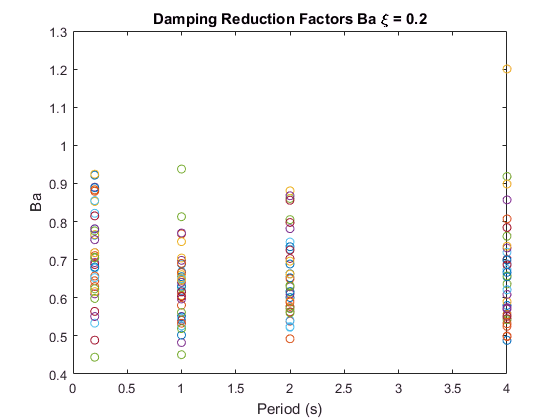

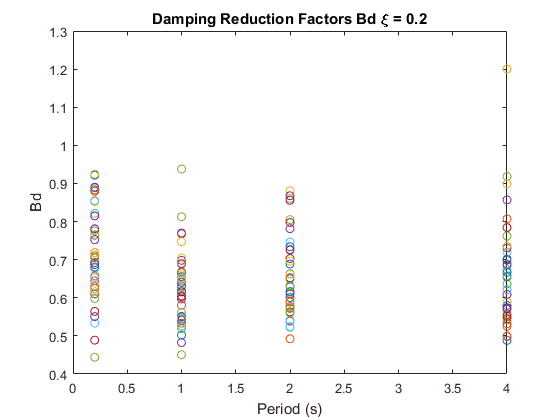

clc; clear; close all;

filename = ["TCU003" "TCU006" "TCU007" "TCU008" "TCU009" "TCU010" "TCU011" "TCU014" "TCU015" "TCU017" "TCU018" "TCU025" "TCU026" "TCU029" "TCU031" "TCU033" "TCU034" "TCU035" "TCU036" "TCU038" "TCU039" "TCU040" "TCU042" "TCU045" "TCU046" "TCU047" "TCU048" "TCU049" "TCU050" "TCU051" "TCU052" "TCU053" "TCU054" "TCU055" "TCU056" "TCU059" "TCU065" "TCU067" "TCU068" "TCU072"];

time_interval = 0.005;

damping_ratios = [0.02 0.05 0.1 0.2];
damping_ratios_name = ["\xi = 2%", "\xi = 5%", "\xi = 10%", "\xi = 20%"];

periods = [0.2 1 2 4];

filename_length = length(filename);
damping_ratios_length = length(damping_ratios);
periods_length = length(periods);

damping_ratio_5_percent = 0.05;

sa_5_percent = zeros(periods_length, filename_length);
sd_5_percent = zeros(periods_length, filename_length);
sa = zeros(periods_length, filename_length);
sd = zeros(periods_length, filename_length);
ba_mean = zeros(periods_length, damping_ratios_length);
bd_mean = zeros(periods_length, damping_ratios_length);

for period_index = 1 : periods_length

    tn = periods(period_index);

    for filename_index = 1 : filename_length

        ag = output_ag_by_filename(filename(filename_index));

        [u, ~, a] = newmark_beta(ag, time_interval, damping_ratio_5_percent, tn, 'average');

        sa_5_percent(period_index, filename_index) = max(abs(a));
        sd_5_percent(period_index, filename_index) = max(abs(u));

    end

end

for damping_index = 1 : damping_ratios_length

    damping_ratio = damping_ratios(damping_index);

    for period_index = 1 : periods_length

        tn = periods(period_index);

        for filename_index = 1 : filename_length

            ag = output_ag_by_filename(filename(filename_index));

            [u, ~, a] = newmark_beta(ag, time_interval, damping_ratio, tn, 'average');

            sa(period_index, filename_index) = max(abs(a));
            sd(period_index, filename_index) = max(abs(u));

        end

    end

    ba = sa ./ sa_5_percent;
    bd = sd ./ sd_5_percent;

    ba_mean(:, damping_index) = mean(ba, 2);
    bd_mean(:, damping_index) = mean(bd, 2);

    figure;
    plot(periods, ba, 'o');
    title(['Damping Reduction Factors Ba \xi = ' num2str(damping_ratio)]);
    xlabel('Period (s)');
    ylabel('Ba');

    figure;
    plot(periods, ba, 'o');
    title(['Damping Reduction Factors Bd \xi = ' num2str(damping_ratio)]);
    xlabel('Period (s)');
    ylabel('Bd');

end

## (2) You should get average from the result of Bd or Ba in each damping ratio and structural period and compare to the codes (Bs or Bl)

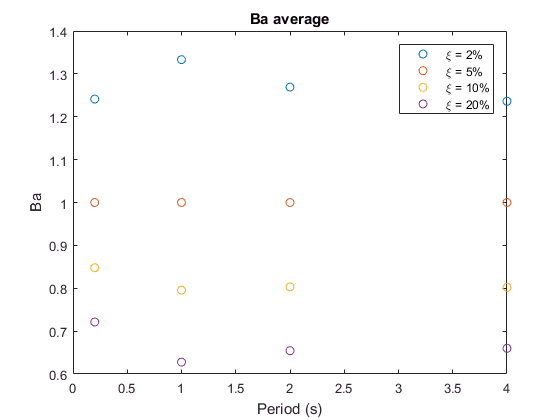

figure;
plot(periods, ba_mean, 'o');
title('Ba average');
legend(damping_ratios_name.', 'Location', 'northeast');
xlabel('Period (s)');
ylabel('Ba');

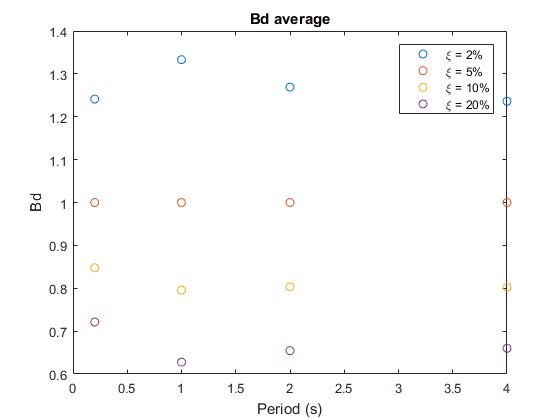

figure;
plot(periods, ba_mean, 'o');
title('Bd average');
legend(damping_ratios_name.', 'Location', 'northeast');
xlabel('Period (s)');
ylabel('Bd');

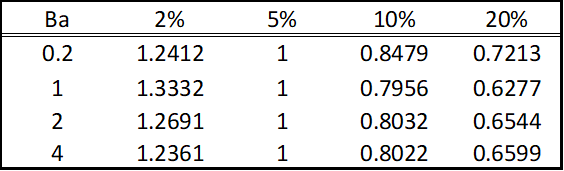

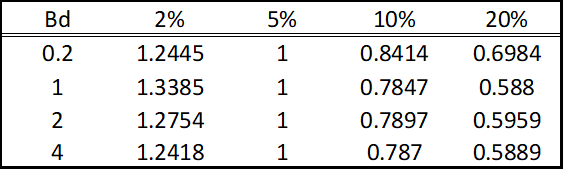

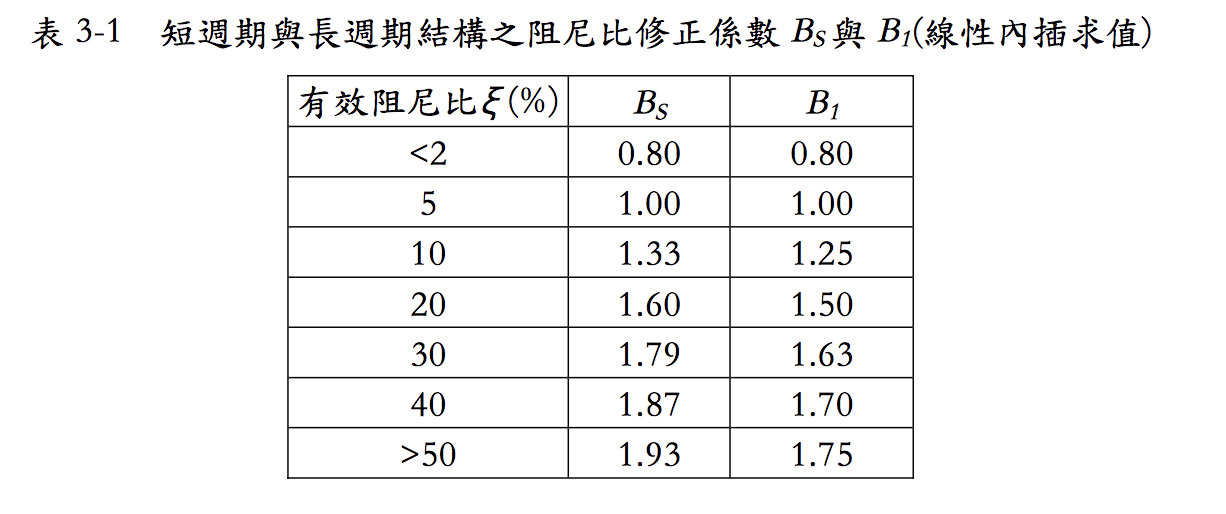

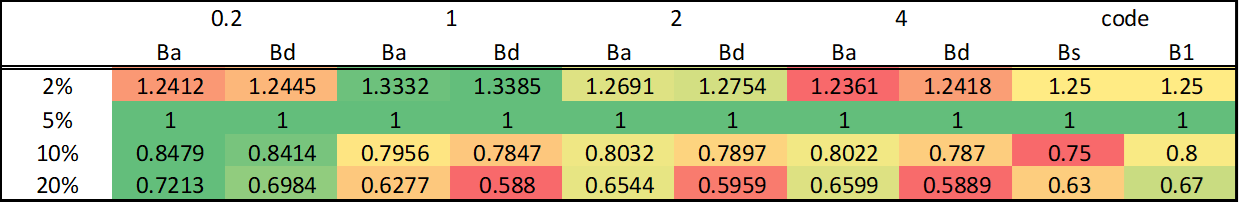

- 阻尼越大折減越多。

- 比較得知，規範對於短週期比較不保守，長週期比較保守。